# Izhikevich spiking model for cortical neurons

This live script is an attempt to reproduce the neuronal dynamics of most cortical neurons by using the Izhikevich model of spiking neurons. It is biologically as plausible as the Hodgkin-Huxley model, yet computationally viable like the integrate-and-fire models. For more information, please see the [original paper](http://www.izhikevich.org/publications/spikes.pdf) of Eugene Izhikevich [*IEEE Trans on Neural Networks, 14(6), 2003*] as well as his book, [Dynamical Systems in Neuroscience](https://www.izhikevich.org/publications/dsn.pdf). 

## 1 The spiking model

### 1.1 Spiking model equation of Izhikevich

The spiking model of cortical neurons is based on the following equations

$C\dot{v} =k\;\left(v-v_r \right)\left(v-v_t \right)-u+I$....................[1]

$\dot{u} =a\left\lbrace b\left(v-v_r \right)-u\right\rbrace$...................................[2] 

$\textrm{If}\;v\ge v_{\textrm{peak}} ,\textrm{then}$$v=c,u=u+d$.................[3]

From: Eugene M. Izhikevich (2007). *Dynamical systems in neuroscience: the geometry of excitability and bursting* (MIT Press).   pp. 273

where $\mathit{\mathbf{v}}$ is the membrane potential, $\mathit{\mathbf{C}}$ is the membrane capacitance and $\mathit{\mathbf{u}}$ is the membrane recovery variable. ${\mathit{\mathbf{v}}}_{\mathit{\mathbf{r}}}$ is the resting membrane potential and ${\mathit{\mathbf{v}}}_{\mathit{\mathbf{t}}}$ is the instantaneous spiking threshold. A large diversity of cortical neurons can be simulated by setting the membrane parameters $\mathit{\mathbf{a}}$, $\mathit{\mathbf{b}}$, $\mathit{\mathbf{c}}$ & $\mathit{\mathbf{d}}$ appropriately (see figure below). 

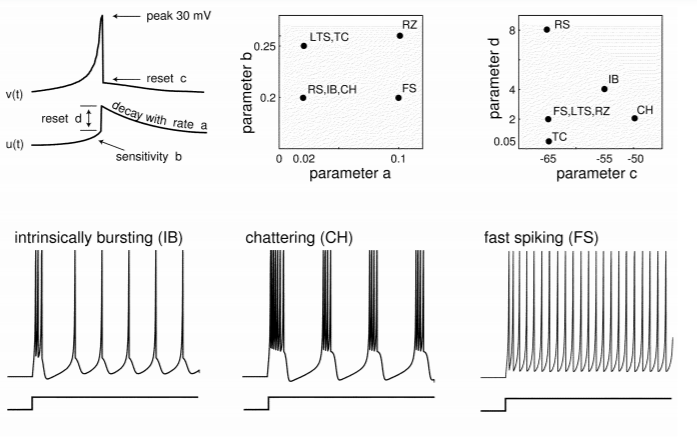

From: Eugene M. Izhikevich (2003). Simple Model of Spiking Neurons, *IEEE Transactions on Neural networks*, 14(6).  

### 1.2 The parameters of the model

#### 1.2.1 Stimulation current parameters

This is the DC current that is injected

params.stm.pulseWidth = 0.7;
params.stm.pulseAmpl = 70;

#### 1.2.2 Membrane parameters

The four parameters of the model $\mathit{\mathbf{a}}$, $\mathit{\mathbf{b}}$, $\mathit{\mathbf{c}}$ & $\mathit{\mathbf{d}}$ control various membrane properties and affect spiking behavior. They are

- $\mathit{\mathbf{a}}$ = recovery time constant

- $\mathit{\mathbf{b}}$ = determines whether recovery variable, $\mathit{\mathbf{u}}$, is an amplifying ($\mathit{\mathbf{b}}$ < 0) or a resonant ($\mathit{\mathbf{b}}$ > 0) variable.

- $\mathit{\mathbf{c}}$ = voltage reset value following spiking

- $\mathit{\mathbf{d}}$ = total amount of outward - inward current during spiking (affects after spiking behaviour)

params.mem.C = 140;          % membrane capacitance
params.mem.vr = -60;       % resting membrane potential
params.mem.vt = -52;         % instantaneous threshold potential
params.mem.a = 0.09;        % recovery time constant
params.mem.b = -0.9;        % determines whether u is amplifying (b<0) or resonant(b>0)
params.mem.c = -70;        % voltage reset value
params.mem.d = 170;          % total outward-inward current during spike
params.mem.vpeak = 17;       % spike cutoff

## 2. Results

### 2.1 Simulation of the Model

The two equations shown above are used to simulate the model according to the forward Euler method. If spiking occurs, membrane potential $\mathit{\mathbf{v}}$ is reset to voltage reset value $\mathit{\mathbf{c}}$ and recovery variable $\mathit{\mathbf{u}}\;$is updated

Here is a plot showing the simulation results

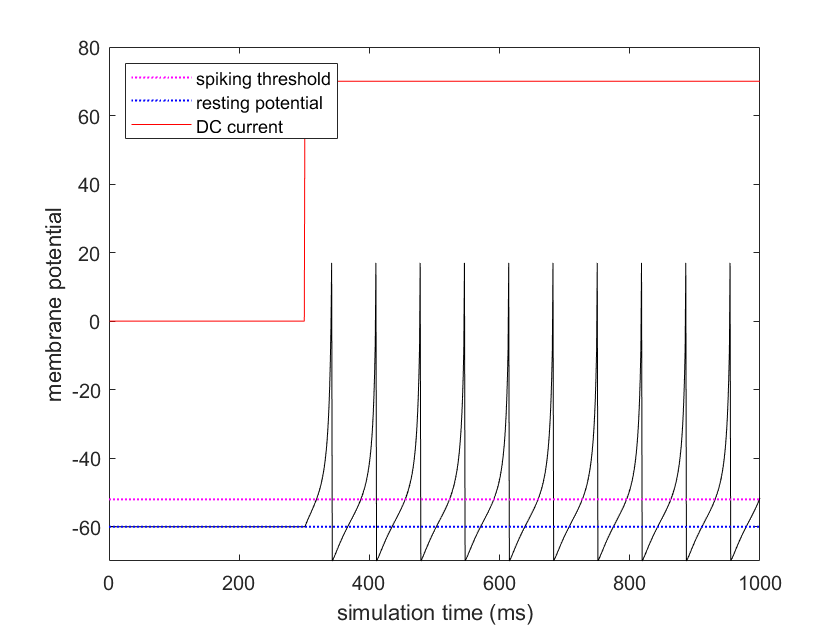

v = simulateIzhikevich(params);

### 2.2 Peak Detection of the simulated pulse train

Here we use a pre-programmed peak detection algorithm from the Live Tasks to detect peaks in the simulated firing pattern of the neuron

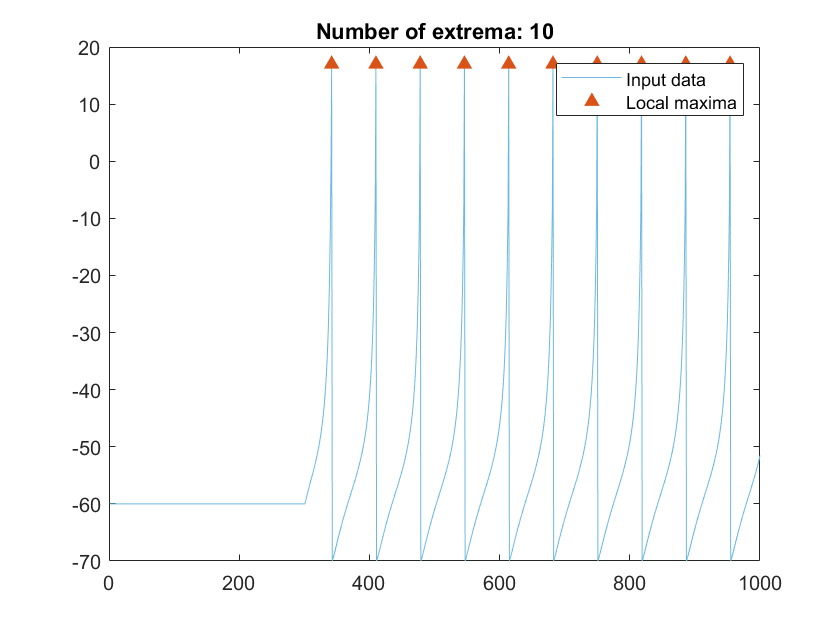

% Find local maxima
maxIndices = islocalmax(v);

% Display results
clf
plot(v,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on

% Plot local maxima
plot(find(maxIndices),v(maxIndices),'^','Color',[217 83 25]/255,...
    'MarkerFaceColor',[217 83 25]/255,'DisplayName','Local maxima')
title(['Number of extrema: ' num2str(nnz(maxIndices))])
hold off
legend

function v = simulateIzhikevich(params)
% initialize/calculate some parameters
T = 1000; tau = 1; % total time of simulation and time step
n = round(T/tau); % simulation time steps
I = [zeros(1,int32((1-params.stm.pulseWidth)*n)),params.stm.pulseAmpl*ones(1,int32(params.stm.pulseWidth*n))]; % DC current
v = params.mem.vr*ones(1,n); u = 0*v; % initial values for membrane potential & recovery

% simulate the model
for i = 1:n-1
    v(i+1)=v(i)+tau*(0.7*(v(i)-params.mem.vr)*(v(i)-params.mem.vt)-u(i)+I(i))/params.mem.C;  % membrane potential
    u(i+1)=u(i)+tau*params.mem.a*(params.mem.b*(v(i)-params.mem.vr)-u(i));                   % membrane rec variable
    
    % if spike occurs, reset membrane potential and recovery variable
    if v(i+1)>=params.mem.vpeak
        v(i)= params.mem.vpeak;
        v(i+1)=params.mem.c;
        u(i+1)=u(i+1)+params.mem.d;
    end
end

% plot the results
plot(tau*(1:n),v,'k'); hold on  % plot the membrane potential
cp = plot(tau*(1:n),I,'r');     % plot the stimulus pulse
% show resting membrane potential and spiking threshold on the figure
vrl = line([0 T],[params.mem.vr params.mem.vr],'color','b','LineStyle',':','LineWidth',1);
vtl = line([0 T],[params.mem.vt params.mem.vt],'color','m','LineStyle',':','LineWidth',1);
% plot aesthetics
ylim([params.mem.vr-10 max(I)+10])
legend([vtl,vrl,cp],{'spiking threshold','resting potential','DC current'},"Location","northwest")
hold off
xlabel('simulation time (ms)')
ylabel('membrane potential')
end

Copyright 2020 The MathWorks, Inc